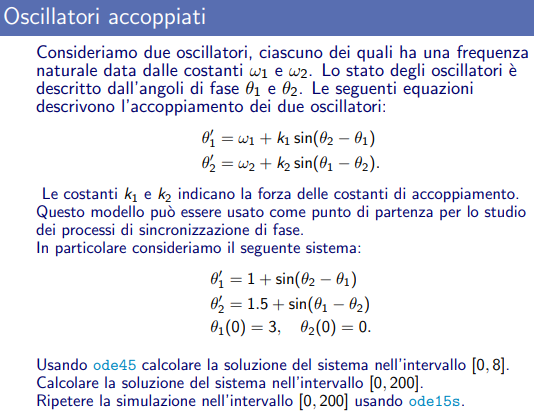

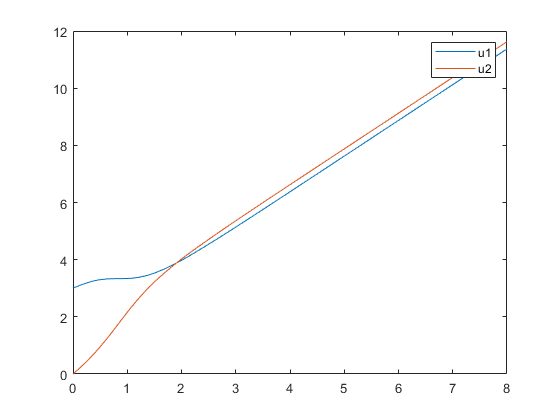

clear all
close all

f = @(t,y) [1+sin(y(2)-y(1)); 1.5+sin(y(1)-y(2))];
y = [3 0];
[t,u] = ode45(f,[0 8],y);
plot(t,u)
legend("u1","u2")

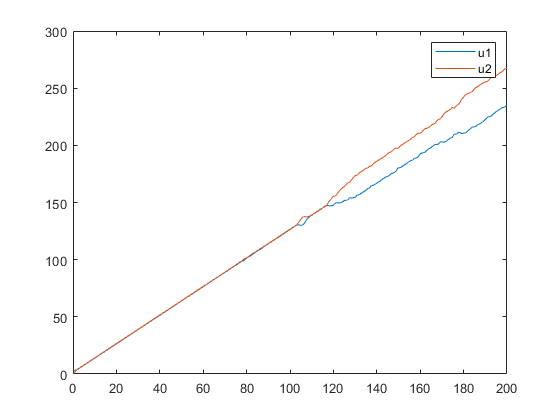

figure
[t,u] = ode45(f,[0 200],y);
plot(t,u)
legend("u1","u2")

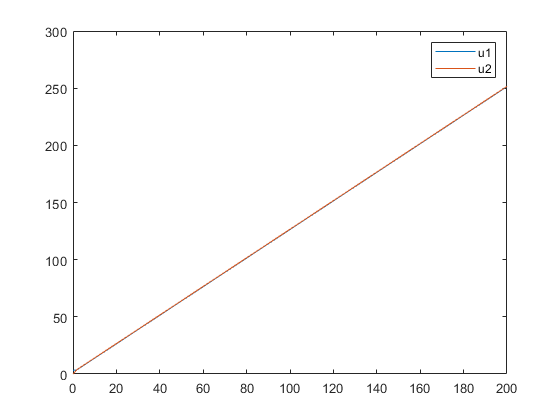

figure
[t,u] = ode15s(f,[0 200],y);
plot(t,u)
legend("u1","u2")

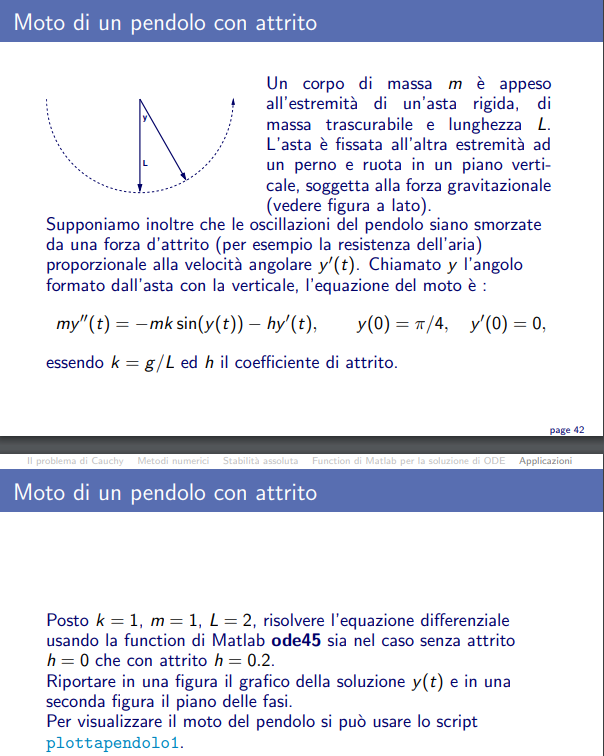

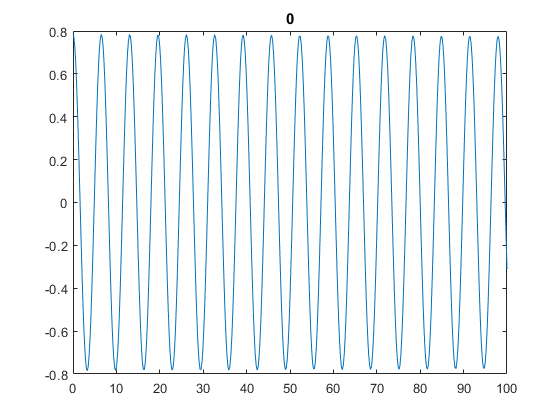

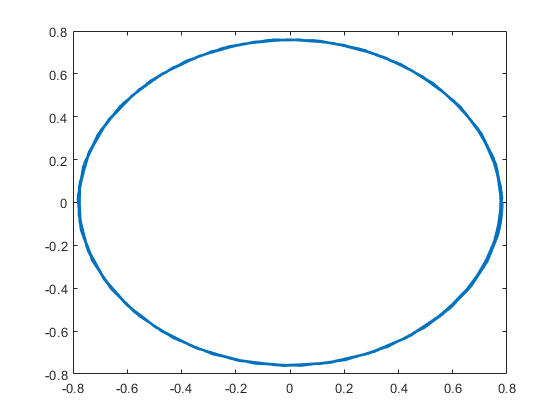

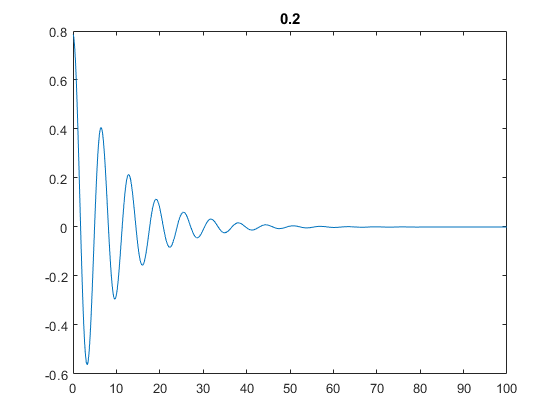

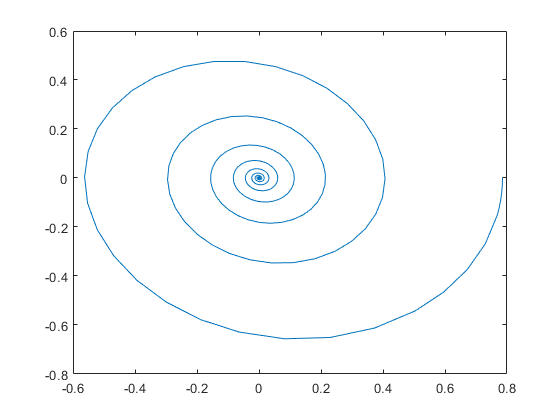

clear all
close all
k=1;m=1;L=2;
h_= [0 0.2];
y=[pi/4 0];
for h = h_
    t = [];
    u= [];
    f  = @(t,z) [z(2); -k.*sin(z(1))-(h.*z(2))./m];
    [t,u] = ode45(f,[0 100],y);
    figure
    plot(t,u(:,1))
    title(h)
    title(h)
    figure
    plot(u(:,1),u(:,2))
    title(h)
    
end

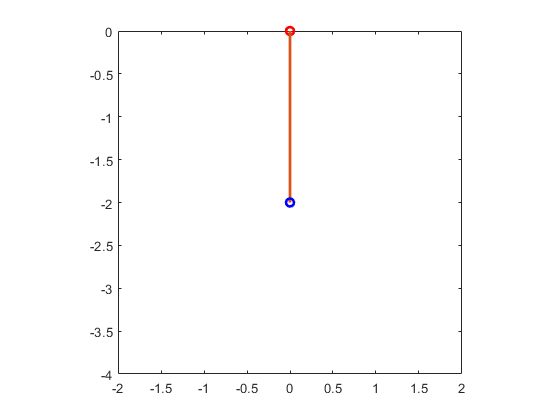

figure
plottapendolo1(t,u(:,1))

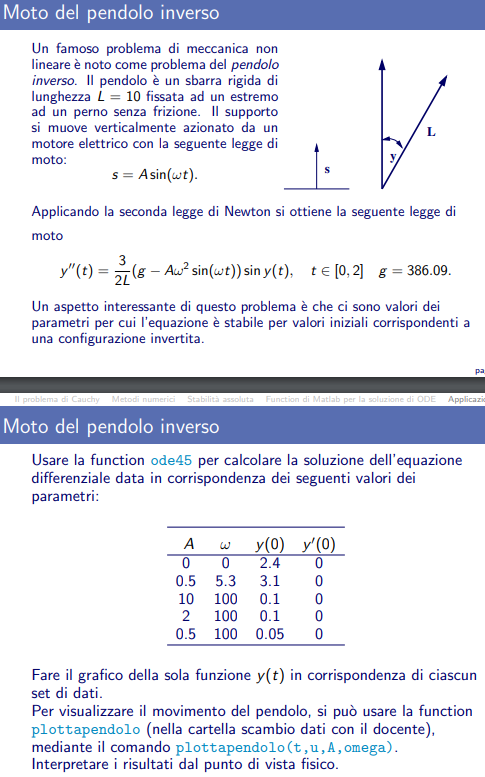

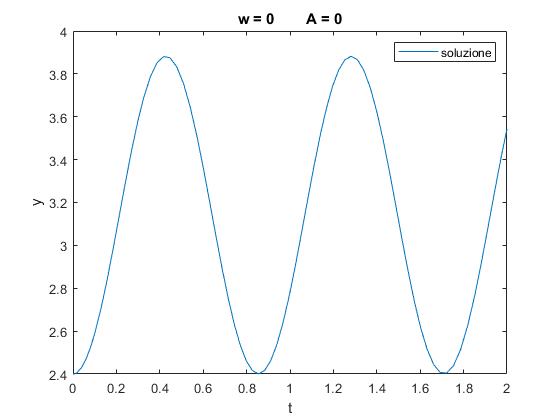

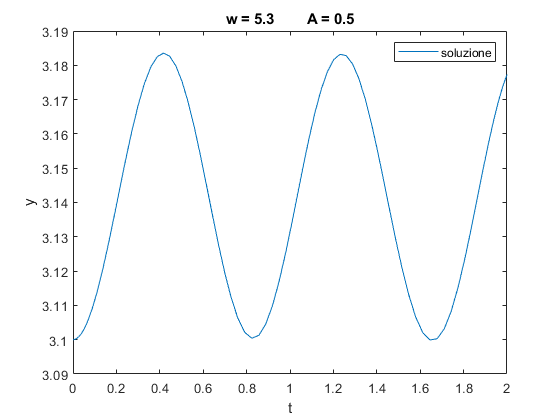

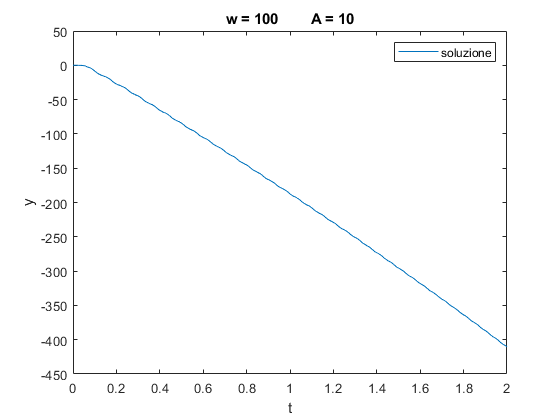

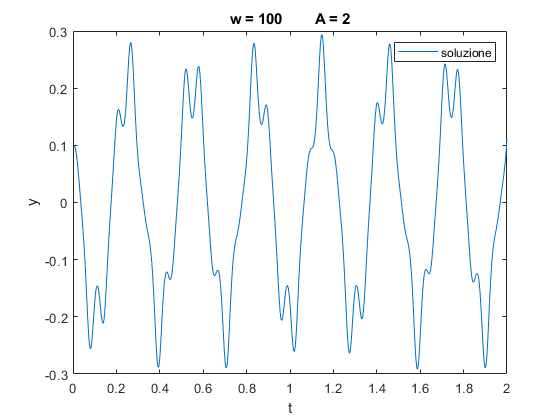

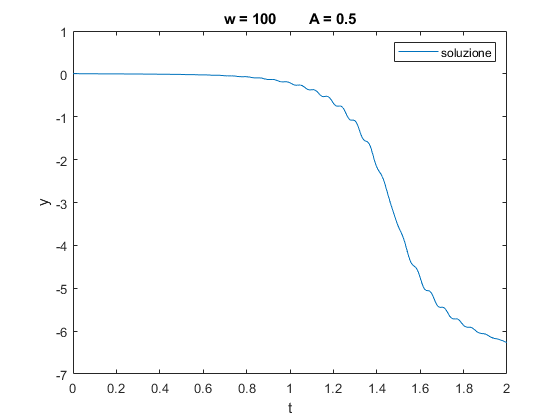

clear all
close all
L = 10;
g = 386.09;
A = [0 0.5 10 2 0.5];
w = [0 5.3 100 100 100];
y0 = [2.4 3.1 0.1 0.1 0.005];
y_0 = [0 0 0 0 0];
for i=1:1:length(A)
    t = [];
    u = [];
    f = @(t,z) [z(2); (3/(2*L)).*(g-A(i)*(w(i))^2.*sin(w(i).*t)).*sin(z(1))];
    [t,u] = ode45(f,[0 2],[y0(i) y_0(i)]);
    figure
    plot(t,u(:,1))
    legend("soluzione")
    xlabel t
    ylabel y
    title("w = "+w(i)+"        A = "+A(i) )
end

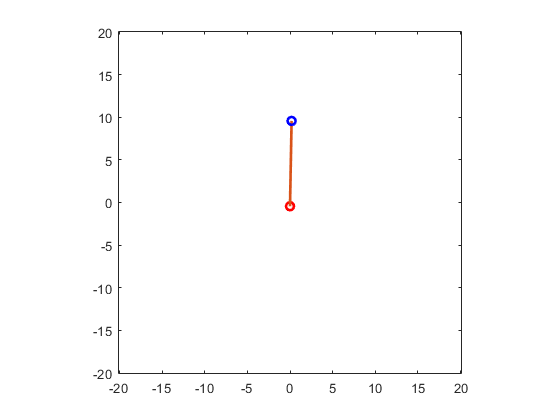

plottapendolo(t,u(:,1),A(i),w(i))

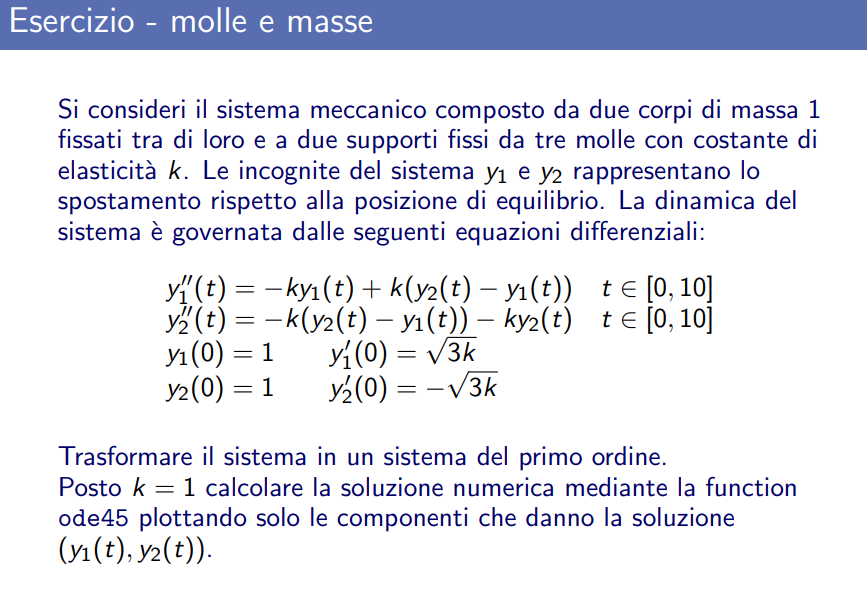

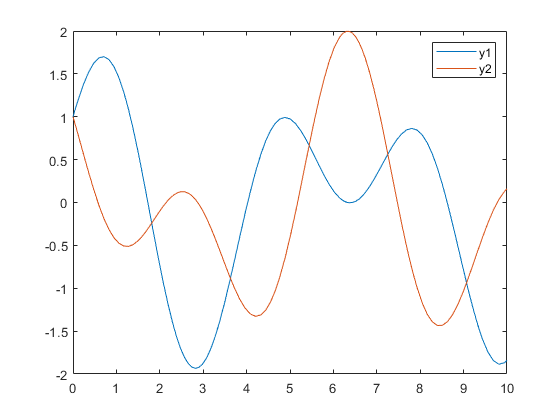

clear all
close all
k = 1;
f = @(t,z) [z(2); -k.*z(1)+k.*(z(3)-z(1)); z(4); -k.*(z(3)-z(1))-(k.*z(3))];
y = [1 sqrt(3*k) 1 -sqrt(3*k)];
[t,u] = ode45(f,[0 10],y);
plot(t,u(:,1),t,u(:,3))
legend("y1","y2")

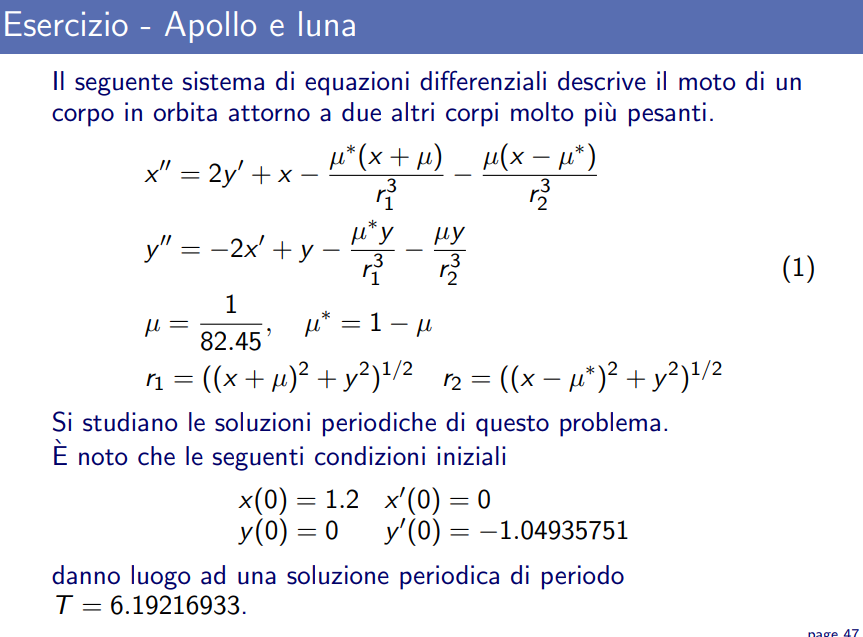

orbita = diagramma delle fasi

clear all
close all
y= [1.2 0 0 -1.04935751];
mu =1/82.45;
mu_ = 1-mu;

r1 = @(t,z) (((z(1) + mu).^2 + z(3).^2).^(1/2)).^3;
r2 = @(t,z) (((z(1) - mu_).^2 + z(3).^2).^(1/2)).^3;

f = @(t,z) [z(2); (2.*z(4))+z(1)-(mu_.*(z(1)+mu))/r1(t,z)-(mu.*(z(1)-mu_))/r2(t,z); z(4); (-2.*z(2))+z(3)-((mu_.*z(3))/(r1(t,z)))-((mu.*z(3))/(r2(t,z)))]

f = function_handle with value:
    @(t,z)[z(2);(2.*z(4))+z(1)-(mu_.*(z(1)+mu))/r1(t,z)-(mu.*(z(1)-mu_))/r2(t,z);z(4);(-2.*z(2))+z(3)-((mu_.*z(3))/(r1(t,z)))-((mu.*z(3))/(r2(t,z)))]

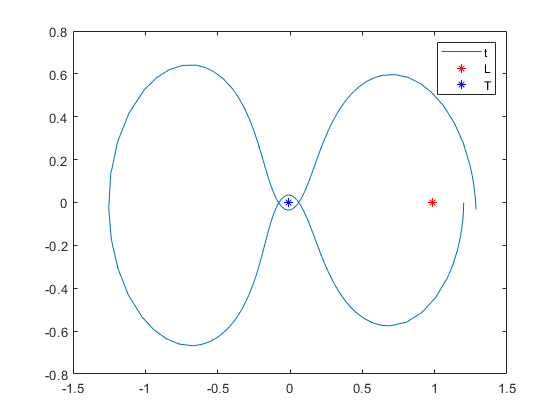


[t,u] = ode45(f,[0 6.192169333],y);
%plot(t,u(:,1),t,u(:,3))
plot(u(:,1),u(:,3))
hold on
plot(1-mu,0,'*r')
plot(-mu,0,'*b')
legend("t","L","T")

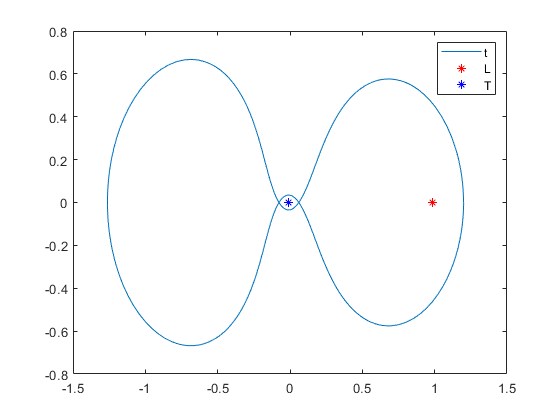

figure
options = odeset('RelTol',1.e-5);
[t,u] = ode45(f,[0 6.192169333],y,options);
plot(u(:,1),u(:,3))
hold on
plot(1-mu,0,'*r')
plot(-mu,0,'*b')
legend("t","L","T")